# Forces & Power Analysis

This script walks through the forces acting on the plane in cruise and how the propulsion system responds to them. By the end you should be able to look at a thrust curve and immediately know whether the plane can fly at a target speed — and how much margin we have.

## Setup and Configuration

% Load aero geometry from XFLR5 and the prop data library.
addpath('src\')

XFLR5_output   = "output.txt";              % path to XFLR5 stability export
prop_lib_path  = "prop_data_library.mat";   % path to prop data .mat file

[aero, geom]     = parseXFLR5(XFLR5_output);
prop_data_library = getPropData(prop_lib_path);

% Prop values and data

V_nom           = 22.2;   % battery nominal voltage          [V]
cap_battery     = 4.2;    % battery capacity                 [Ah]    % set this in livescript
use_battery     = 0.85;   % fraction of battery to use       [-]     % set this in livescript
Kv              = 520;    % motor Kv                         [RPM/V] % set this in livescript
I0              = 1.4;    % motor no-load current            [A]     % set this in livescript
Rm              = 0.016;  % motor winding resistance         [ohm]   % set this in livescript
cruise_throttle = 0.80;   % cruise throttle setting          [-]     % set this in livescript
prop_id         = 62;     % propeller index in library       [-]     % set this in livescript

fprintf('=== Propulsion Setup ===\n')

=== Propulsion Setup ===


fprintf('  Battery  = %.1f Ah  (using %.0f%%)\n', cap_battery, use_battery*100)

  Battery  = 4.2 Ah  (using 85%)


fprintf('  V_nom    = %.1f V\n',  V_nom)

  V_nom    = 22.2 V


fprintf('  Motor Kv = %.0f RPM/V   Rm = %.4f ohm   I0 = %.2f A\n', Kv, Rm, I0)

  Motor Kv = 520 RPM/V   Rm = 0.0160 ohm   I0 = 1.40 A


fprintf('  Prop ID  = %d\n', prop_id)

  Prop ID  = 62


fprintf('  Cruise throttle = %.0f%%\n', cruise_throttle*100)

  Cruise throttle = 80%


## Drag and Velocity

Things are getting real! We want to introduce two types of drag: parasitic and induced. Parasitic drag is due to the form of the aircraft moving through an air. For example, if you like Jeeps, you like the aerodynamic equivalent of a brick and will have a very high parasitic drag on the highway. Induced drag comes from lift directly, and mainly concerns planes. The slower you go, the more lift your wings need to make, and in keeping the plane up, they are also slowly it down. Counterintuitively, this means the minimum drag on an aircraft isn't at the slowest speeds, but at "medium" speeds.

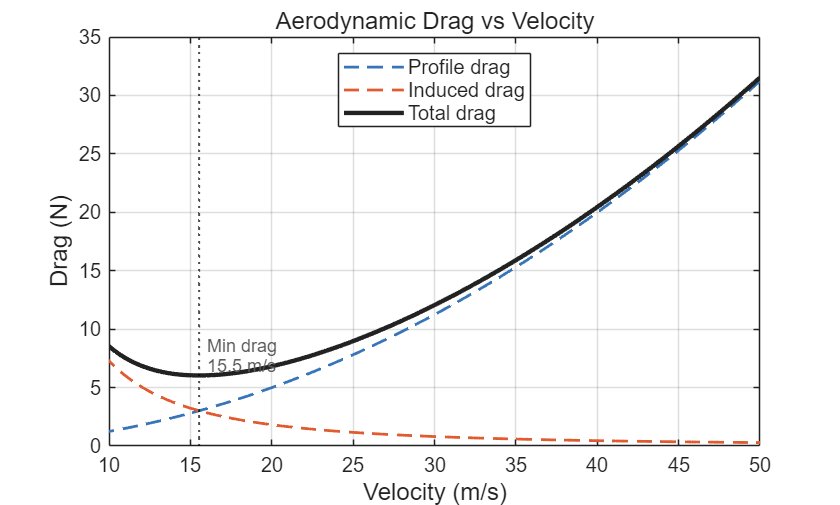

 
% Aerodynamic drag vs. velocity
m   = aero.mass;
S   = geom.S;
AR  = geom.AR;
rho = geom.rho;
g   = 9.81;

% e_oswald = 0.55;       % Oswald efficiency factor  % set this in livescript
% CD0      = aero.CD_profile;   % from XFLR5 operating point

V_range = linspace(5, 50, 300);

% Aerodynamic parameters — from sizing program / design report
% DO NOT use aero.CD_profile for CD0, it only captures wing+tail surfaces
CD0 = 0.05896;  % full aircraft zero-lift drag coefficient  % from sizing program
% AR  = 3.82;     % effective aspect ratio                    % from sizing program  
e   = 0.75;     % Oswald efficiency                         % from sizing program

k = 1 / (pi * e * AR);

D_profile = 0.5 * rho * V_range.^2 * S * CD0;
D_induced = (k * (m*g)^2) ./ (0.5 * rho * V_range.^2 * S);
D_total   = D_profile + D_induced;
P_aero    = D_total .* V_range;

CD_op = aero.CD_profile + aero.CD_induced;
D_op  = 0.5 * rho * aero.V^2 * S * CD_op;
P_op  = D_op * aero.V;

[D_min, idx_min] = min(D_total);
V_min_drag = V_range(idx_min);

figure;
hold on;
plot(V_range, D_profile, '--', 'Color', '#3874B8', 'LineWidth', 1.4, ...
     'DisplayName', 'Profile drag')
plot(V_range, D_induced, '--', 'Color', '#E05C30', 'LineWidth', 1.4, ...
     'DisplayName', 'Induced drag')
plot(V_range, D_total,   '-',  'Color', '#222222', 'LineWidth', 2.2, ...
     'DisplayName', 'Total drag')
% plot(aero.V, D_op, 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r', ...
     % 'DisplayName', sprintf('XFLR5 cruise  (%.1f m/s)', aero.V))
xline(V_min_drag, 'k:', 'LineWidth', 1.0, 'HandleVisibility', 'off')
text(V_min_drag + 0.5, D_min * 1.28, sprintf('Min drag\n%.1f m/s', V_min_drag), ...
     'FontSize', 9, 'Color', [0.35 0.35 0.35])
hold off;
xlabel('Velocity (m/s)', 'FontSize', 12)
ylabel('Drag (N)',        'FontSize', 12)
title('Aerodynamic Drag vs Velocity', 'FontSize', 12, 'FontWeight', 'normal')
legend('Location', 'north', 'FontSize', 10)
xlim([10, 50]);
grid on; box on;

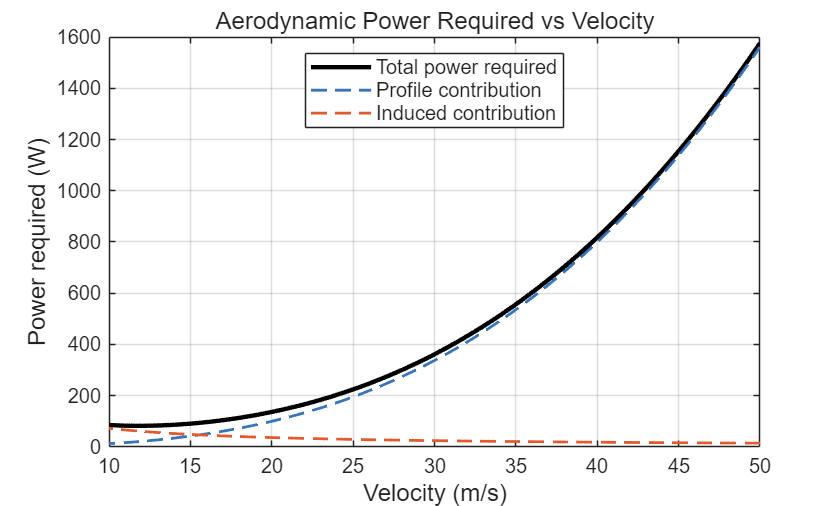


%% 3  ── Aerodynamic Power Required vs Velocity ───────────────────────────
% Power required = drag × velocity.
% This is the minimum power the motor must deliver to the air just to
% maintain level flight at each speed. Actual electrical power consumed
% will be higher once you account for motor and prop efficiency.

figure;
hold on;
plot(V_range, P_aero, 'k-',  'LineWidth', 2.2, 'DisplayName', 'Total power required')
plot(V_range, D_profile .* V_range, '--', 'Color', '#3874B8', ...
     'LineWidth', 1.4, 'DisplayName', 'Profile contribution')
plot(V_range, D_induced .* V_range, '--', 'Color', '#E05C30', ...
     'LineWidth', 1.4, 'DisplayName', 'Induced contribution')
% plot(aero.V, P_op, 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r', ...
%      'DisplayName', sprintf('Cruise point  (%.0f W aero)', P_op))
hold off;
xlabel('Velocity (m/s)',      'FontSize', 12)
ylabel('Power required (W)', 'FontSize', 12)
title('Aerodynamic Power Required vs Velocity', 'FontSize', 12, 'FontWeight', 'normal')
legend('Location', 'north', 'FontSize', 10)
xlim([10, 50]);
grid on; box on;

%% 4  ── Static Thrust vs Throttle (eCalcMain) ────────────────────────────
% Before looking at thrust vs velocity, it's useful to see the static
% picture: how much thrust does this prop/motor make at zero airspeed as
% we sweep throttle? This is what you'd measure on a bench test.
% eCalcMain does exactly this — it sweeps throttle at near-zero velocity.

% [thrusts_static, t_flights_static, powers_static, currents_static, throttles] = ...
%     eCalcMain(V_nom, cap_battery, use_battery, Kv, I0, Rm, prop_id, prop_data_library);
% 
% thrusts_g   = thrusts_static  * 101.97;   % N -> grams (easier to reason about)
% throttles_pct = throttles * 100;
% 
% figure;
% subplot(2, 2, 1);
% plot(throttles_pct, thrusts_g, 'Color', '#3874B8', 'LineWidth', 2.0)
% xlabel('Throttle (%)', 'FontSize', 11)
% ylabel('Static thrust (g)', 'FontSize', 11)
% title('Thrust vs throttle', 'FontSize', 11, 'FontWeight', 'normal')
% grid on; box on;
% 
% subplot(2, 2, 2);
% plot(throttles_pct, powers_static, 'Color', '#E05C30', 'LineWidth', 2.0)
% xlabel('Throttle (%)', 'FontSize', 11)
% ylabel('Power (W)', 'FontSize', 11)
% title('Electrical power vs throttle', 'FontSize', 11, 'FontWeight', 'normal')
% grid on; box on;
% 
% subplot(2, 2, 3);
% plot(throttles_pct, currents_static, 'Color', '#D4880A', 'LineWidth', 2.0)
% xlabel('Throttle (%)', 'FontSize', 11)
% ylabel('Current (A)', 'FontSize', 11)
% title('Current draw vs throttle', 'FontSize', 11, 'FontWeight', 'normal')
% grid on; box on;
% 
% subplot(2, 2, 4);
% valid = t_flights_static > 0 & isfinite(t_flights_static);
% plot(throttles_pct(valid), t_flights_static(valid) / 60, 'Color', '#1A6A3A', 'LineWidth', 2.0)
% yline(5, 'r--', 'LineWidth', 1.2, 'DisplayName', '5 min window')
% xlabel('Throttle (%)', 'FontSize', 11)
% ylabel('Flight time (min)', 'FontSize', 11)
% title('Battery endurance vs throttle', 'FontSize', 11, 'FontWeight', 'normal')
% grid on; box on;
% 
% sgtitle('Static Bench Test — Prop/Motor Performance', 'FontSize', 13, 'FontWeight', 'bold')

## M3 Banner Simulation

As we've found out this year (the hard way), it's all fun and games until you try to launch a massive sheet of ripstop nylon from an aircraft. What stopped our plane from crashing less, was doing the math and simulating its flight beforehand. The first step was the banner: we had to decide on length, as well as aspect ratio. Our initial approach was to model the banner as a smooth, rectangular plate. We know banners flap (a lot), so we were expecting to be underpredicting drag. Working with a smaller banner, we tested its drag in a wind tunnel. Low and behold, our calculations were 20 times smaller than the actual drag. But we knew that now! With our calibration factor `k_turb`, we were able to plot the drag of a banner vs flightspeed.

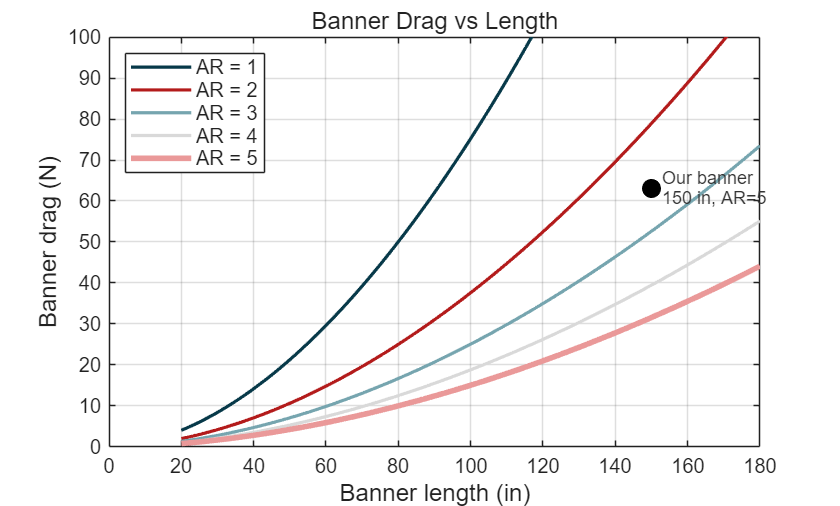

%% M3 — Banner Drag & Mission 3 Drag Polar

% ── Banner parameters ─────────────────────────────────────────────────────
% Set the banner geometry here. We chose AR = 5 for our design.
% Length is variable — change it and both plots update.

L_banner_in = 150;          % banner length              [in]  % set this in livescript
AR_banner   = 5;            % banner aspect ratio (L/H)  [-]   % chosen by team
k_turb      = 20;           % turbulent correction factor [-]   % calibrated from testing (see below)

% Unit conversion
L_banner_m  = L_banner_in * 0.0254;
H_banner_m  = L_banner_m / AR_banner;

% Air properties (carried over from earlier sections)
mu = 1.7894e-5;     % dynamic viscosity  [Pa*s]

% ── Banner drag model ─────────────────────────────────────────────────────
% A banner is just a flat plate being dragged through the air. We model its
% drag using turbulent flat-plate skin friction theory:
%
%   Cf = 0.455 / log10(Re)^2.58       (Schlichting turbulent correlation)
%   D  = k_turb * q * S_wet * Cf
%
% The wetted area is double-sided (air flows over both faces).
% k_turb is a correction factor we calibrated from physical bench testing.
% It accounts for the fact that a floppy banner in real flight doesn't
% behave like a rigid flat plate — it oscillates and billows, generating
% significantly more drag than the idealized model predicts. Our value of
% k_turb = 20 came from matching the model against measured drag data.

% ── Plot 1: Banner drag vs length (multiple ARs) ──────────────────────────
% This is what justified our AR = 5 choice. Higher AR means a longer,
% narrower banner — same length but less height means less wetted area and
% less drag for the same banner score.

V_tow    = 16.0;    % representative M3 tow speed  [m/s]
q_tow    = 0.5 * rho * V_tow^2;

L_sweep_in = linspace(20, 180, 300);
L_sweep_m  = L_sweep_in * 0.0254;
AR_list    = 1:5;

colsBanner = {'#073949', '#B31B1B', '#76A5AF', '#d9d9d9', '#EA9999'};

figure;
hold on;
h_ar = gobjects(numel(AR_list), 1);

for i = 1:numel(AR_list)
    AR_i   = AR_list(i);
    H_i    = L_sweep_m / AR_i;
    S_wet_i = 2 * (L_sweep_m .* H_i);
    Re_i   = (rho * V_tow * L_sweep_m) / mu;
    Cf_i   = 0.455 ./ (log10(Re_i)).^2.58;
    D_i_N  = 0.5 * k_turb * q_tow * S_wet_i .* Cf_i;

    lw_i = 1.6;
    if AR_i == AR_banner, lw_i = 2.8; end

    h_ar(i) = plot(L_sweep_in, D_i_N, '-', ...
        'Color', colsBanner{i}, 'LineWidth', lw_i, ...
        'DisplayName', sprintf('AR = %d', AR_i));
end

% Mark our chosen banner length on AR = 5 curve
H_chosen  = L_banner_m / AR_banner;
S_wet_chosen = 2 * L_banner_m * H_chosen;
Re_chosen = rho * V_tow * L_banner_m / mu;
Cf_chosen = 0.455 / (log10(Re_chosen))^2.58;
D_chosen = k_turb * q_tow * S_wet_chosen * Cf_chosen;

plot(L_banner_in, D_chosen, 'ko', 'MarkerSize', 9, ...
     'MarkerFaceColor', 'k', 'HandleVisibility', 'off')
text(L_banner_in + 3, D_chosen, sprintf('Our banner\n%.0f in, AR=%d', ...
     L_banner_in, AR_banner), 'FontSize', 9, 'Color', [0.2 0.2 0.2])

hold off;
xlabel('Banner length (in)', 'FontSize', 12)
ylabel('Banner drag (N)',  'FontSize', 12)
title('Banner Drag vs Length', 'FontSize', 12, 'FontWeight', 'normal')
legend(h_ar, 'Location', 'northwest', 'FontSize', 10)
xlim([0 180]); ylim([0, 100]);
grid on; box on;

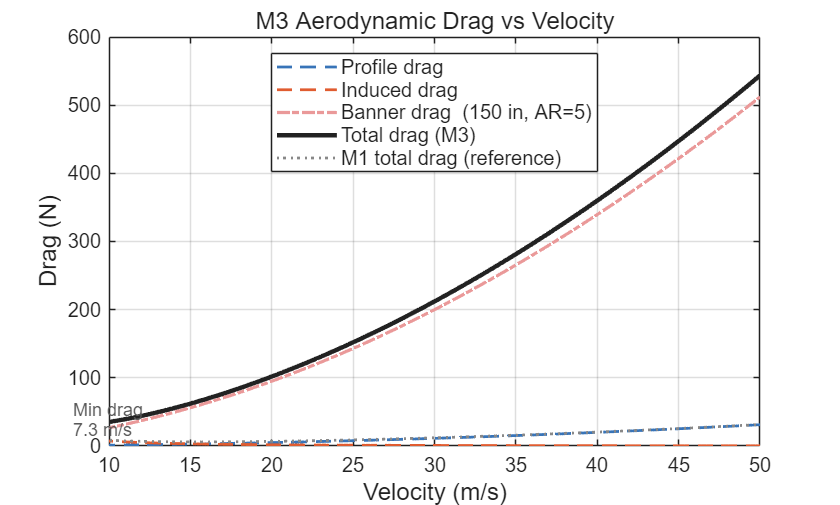


% ── Plot 2: M3 drag polar — aircraft + banner ─────────────────────────────
% Same aircraft as M1 (banner mass is small relative to total).
% Banner drag is added on top of the aircraft polar at each speed.
% Notice the minimum drag speed shifts right compared to M1 — the banner
% adds a roughly speed-squared term, so flying slower is now even more
% costly than in M1.

S_wet_banner = 2 * L_banner_m * H_banner_m;

D_banner_vs_V = zeros(size(V_range));
for i = 1:numel(V_range)
    V_i  = V_range(i);
    Re_i = rho * V_i * L_banner_m / mu;
    Cf_i = 0.455 / (log10(max(Re_i, 1)))^2.58;
    D_banner_vs_V(i) = k_turb * 0.5 * rho * V_i^2 * S_wet_banner * Cf_i;
end

D_total_m3   = D_total + D_banner_vs_V;
P_aero_m3    = D_total_m3 .* V_range;

[D_min_m3, idx_min_m3] = min(D_total_m3);
V_min_drag_m3 = V_range(idx_min_m3);

figure;
hold on;
plot(V_range, D_profile,       '--', 'Color', '#3874B8', 'LineWidth', 1.4, ...
     'DisplayName', 'Profile drag')
plot(V_range, D_induced,       '--', 'Color', '#E05C30', 'LineWidth', 1.4, ...
     'DisplayName', 'Induced drag')
plot(V_range, D_banner_vs_V,   '-.', 'Color', '#EA9999', 'LineWidth', 1.6, ...
     'DisplayName', sprintf('Banner drag  (%.0f in, AR=%d)', L_banner_in, AR_banner))
plot(V_range, D_total_m3,      '-',  'Color', '#222222', 'LineWidth', 2.2, ...
     'DisplayName', 'Total drag (M3)')
plot(V_range, D_total,         ':',  'Color', '#888888', 'LineWidth', 1.4, ...
     'DisplayName', 'M1 total drag (reference)')
xline(V_min_drag_m3, 'k:', 'LineWidth', 1.0, 'HandleVisibility', 'off')
text(V_min_drag_m3 + 0.5, D_min_m3 * 1.28, ...
     sprintf('Min drag\n%.1f m/s', V_min_drag_m3), ...
     'FontSize', 9, 'Color', [0.35 0.35 0.35])
hold off;
xlabel('Velocity (m/s)', 'FontSize', 12)
ylabel('Drag (N)',        'FontSize', 12)
title('M3 Aerodynamic Drag vs Velocity', 'FontSize', 12, 'FontWeight', 'normal')
legend('Location', 'north', 'FontSize', 10)
xlim([10 50]); grid on; box on;

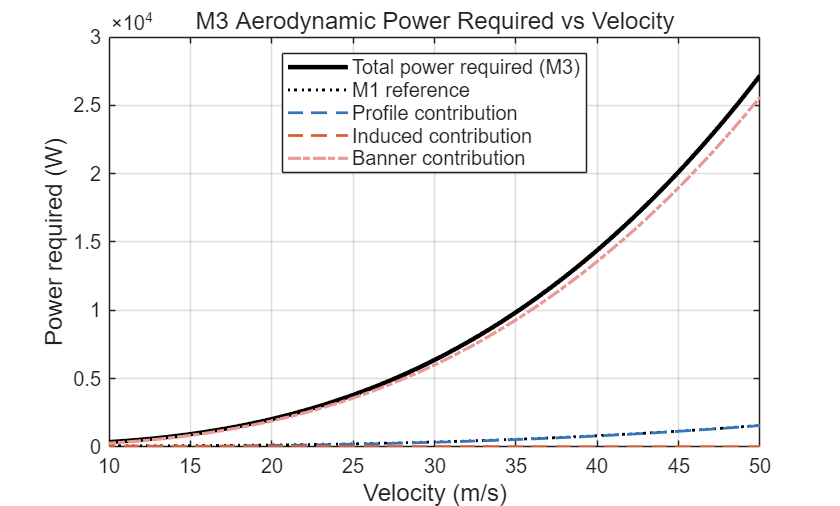


% ── Power required M3 ─────────────────────────────────────────────────────
figure;
hold on;
plot(V_range, P_aero_m3, 'k-',  'LineWidth', 2.2, ...
     'DisplayName', 'Total power required (M3)')
plot(V_range, P_aero,    'k:',  'LineWidth', 1.4, ...
     'DisplayName', 'M1 reference')
plot(V_range, D_profile      .* V_range, '--', 'Color', '#3874B8', 'LineWidth', 1.4, ...
     'DisplayName', 'Profile contribution')
plot(V_range, D_induced      .* V_range, '--', 'Color', '#E05C30', 'LineWidth', 1.4, ...
     'DisplayName', 'Induced contribution')
plot(V_range, D_banner_vs_V  .* V_range, '-.', 'Color', '#EA9999', 'LineWidth', 1.6, ...
     'DisplayName', 'Banner contribution')
hold off;
xlabel('Velocity (m/s)',      'FontSize', 12)
ylabel('Power required (W)',  'FontSize', 12)
title('M3 Aerodynamic Power Required vs Velocity', 'FontSize', 12, 'FontWeight', 'normal')
legend('Location', 'north', 'FontSize', 10)
xlim([10 50]); grid on; box on;


fprintf('\n=== M3 Banner Summary ===\n')


=== M3 Banner Summary ===


fprintf('  Banner:        %.0f in x %.1f in  (AR = %d)\n', ...
        L_banner_in, L_banner_in/AR_banner, AR_banner)

  Banner:        150 in x 30.0 in  (AR = 5)


fprintf('  Banner drag at %.0f m/s:  %.2f N  (%.2f lbf)\n', ...
        V_tow, D_chosen/0.224809, D_chosen)

  Banner drag at 16 m/s:  280.92 N  (63.15 lbf)


fprintf('  M3 min drag speed:  %.1f m/s  (vs %.1f m/s for M1)\n', ...
        V_min_drag_m3, V_min_drag)

  M3 min drag speed:  7.3 m/s  (vs 15.5 m/s for M1)


## Propeller Thrust

The aircraft's drag was half the equation. Now, the goal is to see how fast we can actually go. That means we're looking for an equilibrium. Luckily, everyone who's interviewed for DBF has been asked the question: what are the four main forces acting on an aircraft? In the horizontal direction, we know we're going to see drag balancing out thrust. Since we know the drag as a function of velocity, now it's time to do the same for thrust. 

%% 5  ── Thrust vs Velocity — Does the Plane Fly? ─────────────────────────
% Now sweep velocity. propMain calls propSim at each speed under the given
% throttle setting and fits a quadratic.
%
% Plotting thrust and drag on the same axes answers the key question:
% is thrust > drag at your target speed? The crossing point is where the
% plane reaches equilibrium — it can't go faster than that at this throttle.
cruise_throttle = 0.85;

[thrusts_fit_cruise, t_flights_fit_cruise, powers_fit_cruise, ~, velocities] = ...
    propMain(V_nom, cap_battery, use_battery, Kv, I0, Rm, ...
             cruise_throttle, prop_id, prop_data_library);

% [thrusts_fit_max, t_flights_fit_max, powers_fit_max, ~, ~] = ...
%     propMain(V_nom, cap_battery, use_battery, Kv, I0, Rm, ...
%              1.0, prop_id, prop_data_library);

T_cruise = polyval(thrusts_fit_cruise, V_range);
% T_max    = polyval(thrusts_fit_max,    V_range);

% Find equilibrium (thrust = drag crossing)
diff_sign = diff(sign(T_cruise - D_total));
idx_eq    = find(diff_sign ~= 0, 1, 'last');
V_eq      = NaN;
if ~isempty(idx_eq)
    V_eq = V_range(idx_eq); 
end

figure;
hold on;
% plot(V_range, T_max,    '-',  'Color', '#E05C30', 'LineWidth', 2.2, ...
%      'DisplayName', 'Thrust — full throttle')
plot(V_range, T_cruise, '-',  'Color', '#3874B8', 'LineWidth', 2.2, ...
     'DisplayName', sprintf('%.0f%% throttle', cruise_throttle*100))
if ~isnan(V_eq)
    plot(V_eq, polyval(thrusts_fit_cruise, V_eq), 'x', ...
         'MarkerSize', 13, 'LineWidth', 2.2, ...
         'DisplayName', sprintf('Equilibrium'))
end
plot(V_range, D_total,  'k--', 'LineWidth', 1.8, ...
     'DisplayName', 'Drag required')

fprintf("Equilibrium speed: %.1f", V_eq);

Equilibrium speed: 33.9

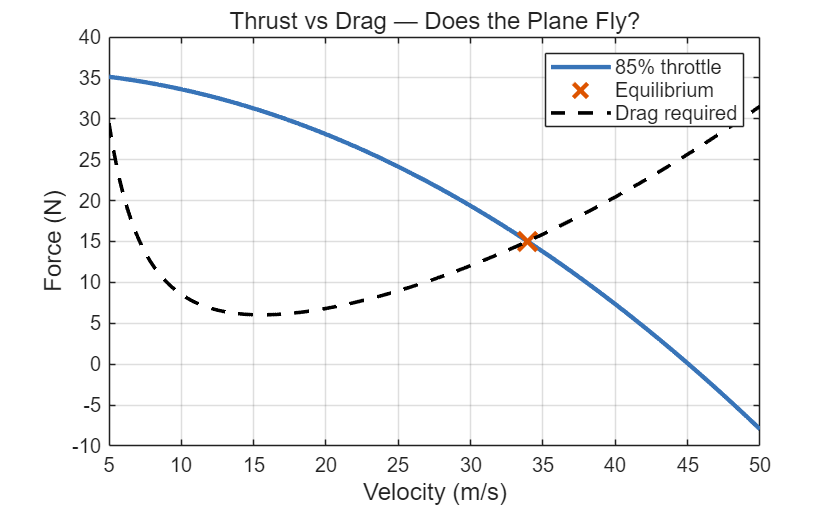


hold off;
xlabel('Velocity (m/s)', 'FontSize', 12)
ylabel('Force (N)',       'FontSize', 12)
title('Thrust vs Drag — Does the Plane Fly?', 'FontSize', 12, 'FontWeight', 'normal')
legend('Location', 'northeast', 'FontSize', 10)
grid on; box on;

ylim([0, max(T_max) * 1.2])

Unrecognized function or variable 'T_max'.


%% 6  ── Electrical Power & Flight Time vs Velocity ───────────────────────
% Finally, how does electrical power consumption and endurance look
% across the speed range? The gap between aero power and electrical power
% is system losses (motor heat, prop efficiency). Bigger gap = worse system.
% 
% P_elec_cruise = polyval(powers_fit_cruise, V_range);
% P_elec_max    = polyval(powers_fit_max,    V_range);
% P_elec_cruise = max(P_elec_cruise, 0);
% P_elec_max    = max(P_elec_max,    0);
% 
% t_flight_cruise = max(polyval(t_flights_fit_cruise, V_range), 0);
% t_flight_max    = max(polyval(t_flights_fit_max,    V_range), 0);
% 
% figure;
% 
% subplot(2, 1, 1);
% hold on;
% plot(V_range, P_elec_max    / 1000, '-',  'Color', '#E05C30', 'LineWidth', 2.0, ...
%      'DisplayName', 'Electrical — full throttle')
% plot(V_range, P_elec_cruise / 1000, '-',  'Color', '#3874B8', 'LineWidth', 2.0, ...
%      'DisplayName', sprintf('Electrical — %.0f%% throttle', cruise_throttle*100))
% plot(V_range, P_aero        / 1000, 'k--', 'LineWidth', 1.6, ...
%      'DisplayName', 'Aero power required')
% plot(aero.V, P_op / 1000, 'ro', 'MarkerSize', 9, 'MarkerFaceColor', 'r', ...
%      'HandleVisibility', 'off')
% hold off;
% ylabel('Power (kW)', 'FontSize', 11)
% title('Electrical Power vs Velocity', 'FontSize', 12, 'FontWeight', 'normal')
% legend('Location', 'north', 'FontSize', 9)
% grid on; box on;
% 
% subplot(2, 1, 2);
% hold on;
% plot(V_range, t_flight_max    / 60, '-',  'Color', '#E05C30', 'LineWidth', 2.0, ...
%      'DisplayName', 'Full throttle')
% plot(V_range, t_flight_cruise / 60, '-',  'Color', '#3874B8', 'LineWidth', 2.0, ...
%      'DisplayName', sprintf('%.0f%% throttle', cruise_throttle*100))
% yline(5, 'k--', 'LineWidth', 1.4, 'DisplayName', '5 min mission window')
% plot(aero.V, polyval(t_flights_fit_cruise, aero.V) / 60, 'ro', ...
%      'MarkerSize', 9, 'MarkerFaceColor', 'r', 'HandleVisibility', 'off')
% hold off;
% xlabel('Velocity (m/s)',    'FontSize', 11)
% ylabel('Flight time (min)', 'FontSize', 11)
% title('Estimated Flight Time vs Velocity', 'FontSize', 11, 'FontWeight', 'normal')
% legend('Location', 'northeast', 'FontSize', 9)
% grid on; box on;

% %% Summary ────────────────────────────────────────────────────────────────
% fprintf('\n=== Cruise Point Summary ===\n')
% fprintf('  XFLR5 cruise speed    = %.2f m/s\n',  aero.V)
% fprintf('  Drag at cruise        = %.2f N\n',     D_op)
% fprintf('  Aero power required   = %.1f W\n',     P_op)
% fprintf('  Thrust at cruise      = %.2f N\n',     polyval(thrusts_fit_cruise, aero.V))
% fprintf('  Elec power consumed   = %.1f W\n',     polyval(powers_fit_cruise,  aero.V))
% t_s = polyval(t_flights_fit_cruise, aero.V);
% fprintf('  Est. flight time      = %.1f s  (%.2f min)\n', t_s, t_s/60)
% if ~isnan(V_eq)
%     fprintf('  Max cruise speed      = %.1f m/s  (thrust = drag)\n', V_eq)
% end